# FINO1: An overview of the turbulence characteristics

This script provides visualizations to understand the turbulence characteristics on FINO1 based on wind data, based on the following papers [1,2,3]. The data are available on Zenodo [4].

[1] Cheynet, E., Jakobsen, J. B., & Obhrai, C. (2017). Spectral characteristics of surface-layer turbulence in the North Sea. *Energy Procedia*, 137, 414-427. Elsevier.

[2] Cheynet, E., Jakobsen, J. B., & Reuder, J. (2018). Velocity spectra and coherence estimates in the marine atmospheric boundary layer. *Boundary-layer meteorology*, 169(3), 429-460. Springer Netherlands.

[3] Cheynet, E. (2019). Influence of the Measurement Height on the Vertical Coherence of Natural Wind. *Lecture Notes in Civil Engineering*, 27, 207-221. Springer

[4] `https://doi.org/10.5281/zenodo.8296894`

## Load the data

The data are stored in the folder **dataAnalysed. **The data and/or notations are defined as follow:

1. **u, v, w**: These represent the three components of wind velocity in Cartesian coordinates. Typically, 'u' is the wind speed in the direction of the main flow (often east-west), 'v' is perpendicular to 'u' (often north-south), and 'w' is the vertical wind speed.

2. **T**: This is the air temperature.

3. **U**: This is the mean wind speed, typically the magnitude of the resultant of the `u` and `v` components.

4. **meanT**: This denotes the mean sonic temperature, which is often measured using sonic anemometers.

5. **meanDir**: This represents the mean wind direction over a given time period.

6. **stdX**: This indicates the standard deviation of a given variable, where `X` can be a velocity component (u, v, w) or temperature (T). It measures the fluctuations of the variable from its mean value.

7. **Luz, Lvz, Lwz**: These are the vertical turbulence length scales for the respective velocity components. They give an idea of the size of the eddies or turbulent structures in the vertical direction for each component.

8. **zL**: This is the non-dimensional stability parameter. It's calculated as the ratio of the height above the surface `z` to the Obukhov length `L`. \(zL = \frac{z}{L}\).

9. **L**: Known as the Obukhov length, it characterizes the relative importance of buoyant and inertial forces on turbulent flows. It's crucial for stability classification in boundary layer meteorology.

10. **z**: This represents the height above the surface (or ground).

11. **T_star**: This is the scaling temperature, which is used in similarity theory to scale temperature measurements in the turbulent boundary layer.

12. **u_star**: Referred to as the friction velocity, it's a velocity scale that characterizes the strength of turbulent eddies in the boundary layer.

13. **wT, uw, vw**: These are covariance estimates derived from the Reynolds stress tensor. For instance, \(uw = \overline{u'w'}\), where the overbar denotes a time average. The covariance gives insights into the interactions between velocity components and temperature.

14. **Result_RA**: This is the result from the reverse arrangement test, a method used to check the stationarity of a time series.

15. **Su,Sv,Sw**: This represents the one-point velocity spectra for each velocity component. It provides information about the distribution of energy across different frequency ranges for the turbulent fluctuations.

16. **Suw**: This is the cross-spectrum between `u` and `w`, which shows the shared frequency content between the two velocity components.

17. :**f** This is the frequency, typically used in spectral analysis to understand the scales of turbulent motion.

Each of these variables is crucial in understanding, measuring, or analyzing the characteristics of turbulence in wind energy and boundary-layer meteorolgy.


clearvars;close all;clc;

data = dir('./dataAnalysed/*.mat');
Ndata = numel(data);

if Ndata==0,
   error('Data not found or not in the correct folder. Try to download them from https://doi.org/10.5281/zenodo.8296894')
end

[U, meanT, meanDir, stdU, stdV, stdW, stdT, Luz, Lvz, Lwz, zL, L,...
    u_star, T_star, wT, uw, vw, Result_RA, Su, Sv, Sw, Suw,f] = mergeWindData(data);


% Define sensor heights. The variable 'z' denotes heights at which sensors are located.
% indSensor = 1 is for sensor at 81 m
% indSensor = 2 is for sensor at 61 m
% indSensor = 3 is for sensor at 41 m
z = [81.5, 61.5, 41.5];

## Mean flow characteristics

Mean wind speed under 5 m/s are not included in the dataset. Mean wind directions below 180 deg are not included in the dataset as wind speed data associated with a direction of less than 180 deg may beaffected by mast shadowing.

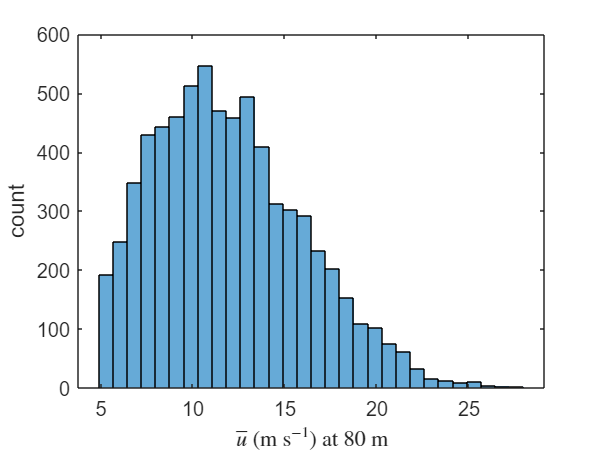

clf;close all;
figure
histogram(U(1,:),30,'normalization','count')
ylabel('count')
xlabel('$\overline{u} $ (m s$^{-1}$) at 80 m','interpreter','latex')

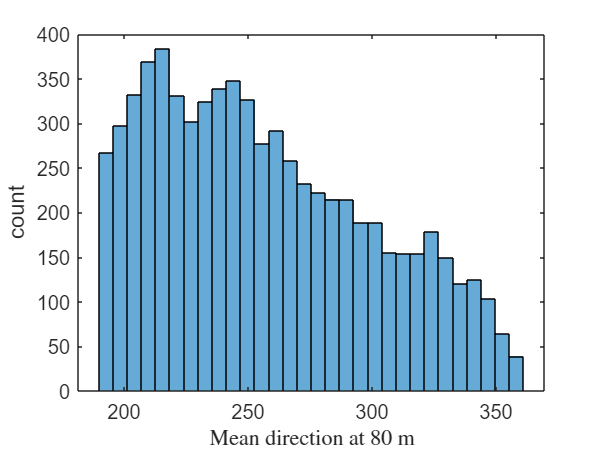


figure
histogram(meanDir(1,:),30,'normalization','count')
ylabel('count')
xlabel('Mean direction at 80 m','interpreter','latex')

## Visualize u* as a function of stdU (near neutral conditions)

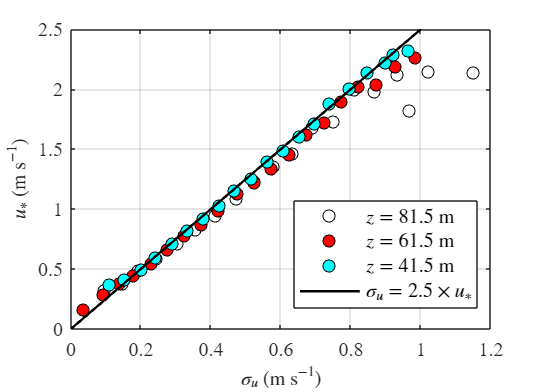


clf;close all
figure('position',[360   357   362   261])
COLOR = {'w','r','c'};
clear leg
for kk=1:numel(z),
    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<0.1);
    [y,x,~] = binAveraging(stdU(kk,ind),...
        u_star(kk,ind),'Nbin',20,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
    leg{kk}=['$z = ',num2str(z(kk)), '$ m'];
end

plot([0 1.0],2.5.*[0 1.0],'k','linewidth',1.2)
leg{kk+1} = '$\sigma_u = 2.5 \times u_*$';

ylabel('$u_*$ (m s$^{-1}$)','interpreter','latex')
xlabel('$\sigma_u$ (m s$^{-1}$)','interpreter','latex')
set(gcf,'color','w')
l= legend(leg{:});set(l,'interpreter','latex','location','best')
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

## Visualize turbulence intensities Iu, Iv and Iw

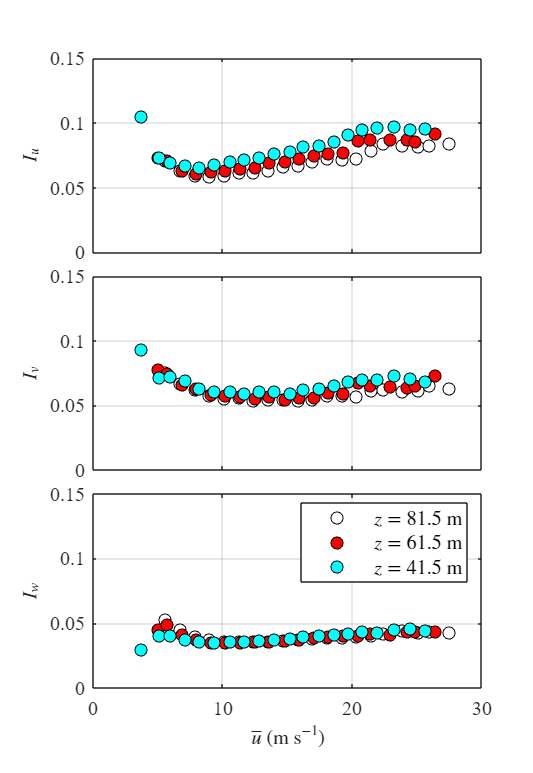


clf;close all
figure('position',[360   103   355   515])
tiledlayout(3,1,"TileSpacing","tight")
COLOR = {'w','r','c'};
nexttile
clear leg

% Loop to plot turbulence intensity for 'u' component across
% different sensor heights
for kk=1:numel(z),
    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<2);
    [y,x,~] = binAveraging(stdU(kk,ind)./U(kk,ind),...
        U(kk,ind),'Nbin',20,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
    xlim([0 30])
    ylim([0 ,0.15])
    leg{kk}=['$z = ',num2str(z(kk)), '$ m'];
end
ylabel('$I_u$','interpreter','latex')
set(gca,'XTickLabel',[]);

% Loop to plot turbulence intensity for 'v' component across
% different sensor heights

nexttile
clear ind
for kk=1:numel(z),
    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<2);
    [y,x,~] = binAveraging(stdV(kk,ind)./U(kk,ind),...
        U(kk,ind),'Nbin',20,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
    xlim([0 30])
    ylim([0 ,0.15])
end
ylabel('$I_v$','interpreter','latex')
set(gca,'XTickLabel',[]);

nexttile
clear ind
for kk=1:numel(z),
    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<2);
    [y,x,~] = binAveraging(stdW(kk,ind)./U(kk,ind),...
        U(kk,ind),'Nbin',20,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
    xlim([0 30])
    ylim([0 ,0.15])
end
set(gcf,'color','w')
ylabel('$I_w$','interpreter','latex')
xlabel('$\overline{u}$ (m s$^{-1}$)','Interpreter','latex')
l= legend(leg{:});set(l,'interpreter','latex','location','best')
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

## Visualize turbulence standard deviation ratios (neutral conditions)

This section of the code visualizes the standard deviation ratios of the turbulence components under near-neutral conditions. The visualization is done for two standard deviation ratios: σ_v/σ_u and σ_w/σ_u.

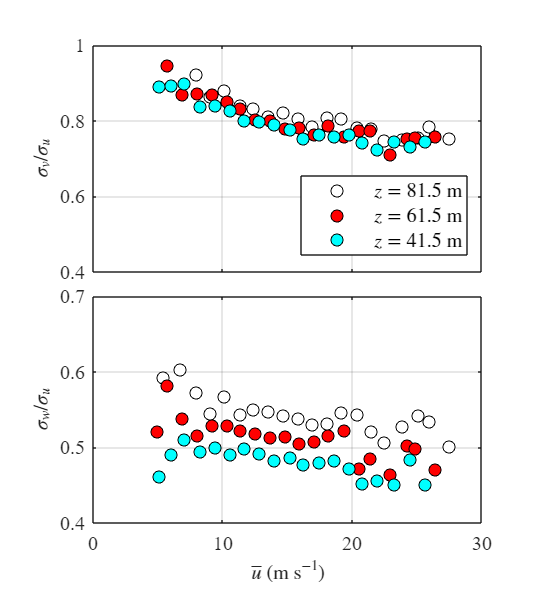


clf;close all
figure('position',[360   103   355   400])
tiledlayout(2,1,"TileSpacing","tight")
COLOR = {'w','r','c'};
nexttile
clear leg
for kk=1:numel(z),

    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<0.1);
    [y,x,~] = binAveraging(stdV(kk,ind)./stdU(kk,ind),...
        U(kk,ind),'Nbin',20,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
    xlim([0 30])
    ylim([0.4 ,1])
    leg{kk}=['$z = ',num2str(z(kk)), '$ m'];
end
ylabel('$\sigma_v/\sigma_u$','interpreter','latex')
set(gca,'XTickLabel',[]);
l= legend(leg{:});set(l,'interpreter','latex','location','best')

nexttile
for kk=1:numel(z),
    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<0.1);
    [y,x,~] = binAveraging(stdW(kk,ind)./stdU(kk,ind),...
        U(kk,ind),'Nbin',20,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
    xlim([0 30])
    ylim([0.4 ,0.7])
end
ylabel('$\sigma_w/\sigma_u$','interpreter','latex')

set(gcf,'color','w')
xlabel('$\overline{u}$ (m s$^{-1}$)','Interpreter','latex')

set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

## Visualize STD

` This section of the code visualizes the normalized standard deviations of the wind components as functions of the stability parameter z/L.`

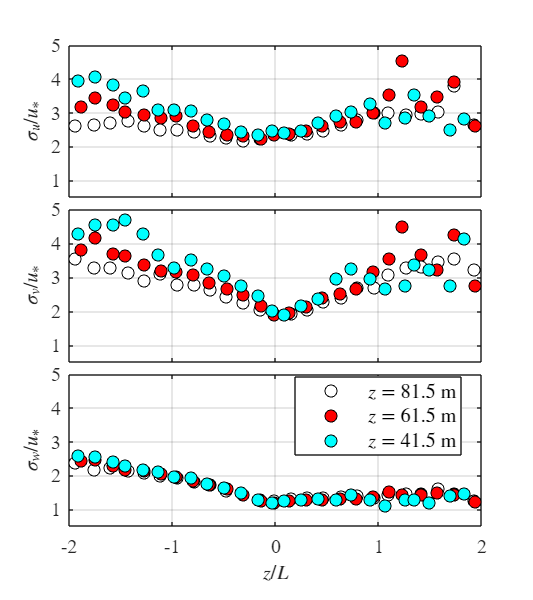


clf;close all
figure('position',[360   103   355   400])
tiledlayout(3,1,"TileSpacing","tight")
COLOR = {'w','r','c'};
nexttile
for kk=1:numel(z),

    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<2);
    [y,x,~] = binAveraging(stdU(kk,ind)./u_star(kk,ind),...
        zL(kk,ind),'Nbin',25,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
end
xlim([-2,2])
ylim([0.5 ,5])
ylabel('$\sigma_u/u_*$','Interpreter','latex')
set(gca,'xticklabel',[])

nexttile
clear ind
for kk=1:numel(z),

    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<2);
    [y,x,~] = binAveraging(stdV(kk,ind)./u_star(kk,ind),...
        zL(kk,ind),'Nbin',25,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
end
xlim([-2,2])
ylim([0.5 ,5])
ylabel('$\sigma_v/u_*$','Interpreter','latex')
set(gca,'xticklabel',[])

clear ind leg
nexttile
for kk=1:numel(z),
    ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(zL(kk,:))<2);
    [y,x,~] = binAveraging(stdW(kk,ind)./u_star(kk,ind),...
        zL(kk,ind),'Nbin',25,'averaging','median');
    plot(x,y,'ko','MarkerFaceColor',COLOR{kk});
    grid on
    hold on
    leg{kk}=['$z = ',num2str(z(kk)), '$ m'];
end
xlim([-2,2])
ylim([0.5 ,5])
ylabel('$\sigma_w/u_*$','Interpreter','latex')
xlabel('$z/L$','interpreter','latex')
set(gcf,'color','w')
l= legend(leg{:});set(l,'interpreter','latex','location','best')


set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

## Cross-wind turbulence length scales 

The length scales of interest are $L^z_u, L^z_v \text{ and }  L^z_w$

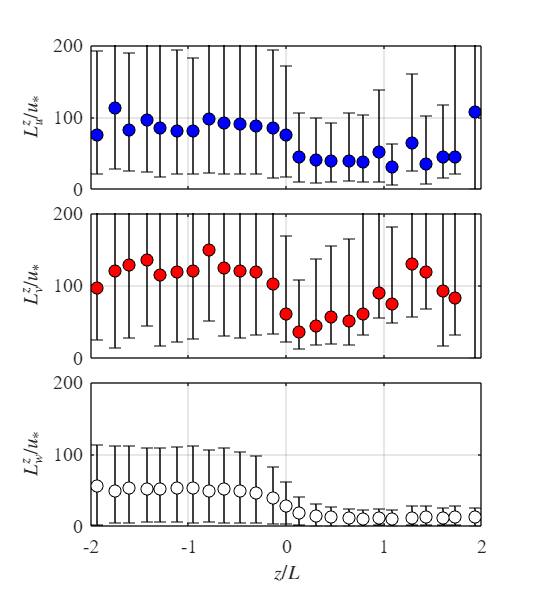

clf;close all
clear kk ind

figure('position',[360   103   355   400])
tiledlayout(3,1,"TileSpacing","tight")
nexttile
ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(mean(zL,'omitnan'))<2);
[y,x,stdy] = binAveraging(Luz(ind),...
    mean(zL(:,ind),'omitnan'),'Nbin',25,'averaging','median',...
    'dispersion','decile_25_75');
errorbar(x,y,stdy(:,1),stdy(:,2),'ko','MarkerFaceColor','b');
grid on
hold on
xlim([-2,2])
ylim([0 200])
ylabel('$L^z_u/u_*$','Interpreter','latex')
set(gca,'xticklabel',[])

nexttile
clear ind

ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(mean(zL,'omitnan'))<2);
[y,x,stdy] = binAveraging(Lvz(ind),...
    mean(zL(:,ind),'omitnan'),'Nbin',25,'averaging','median',...
    'dispersion','decile_25_75');
errorbar(x,y,stdy(:,1),stdy(:,2),'ko','MarkerFaceColor','r');
grid on
hold on
xlim([-2,2])
ylim([0 200])
ylabel('$L^z_v/u_*$','Interpreter','latex')
set(gca,'xticklabel',[])

clear ind leg
nexttile
ind = find(meanDir(1,:)<360 & meanDir(1,:)>190 & abs(mean(zL,'omitnan'))<2);
[y,x,stdy] = binAveraging(Lwz(ind),...
    mean(zL(:,ind),'omitnan'),'Nbin',25,'averaging','median',...
    'dispersion','decile_25_75');
errorbar(x,y,stdy(:,1),stdy(:,2),'ko','MarkerFaceColor','w');
grid on
hold on
xlim([-2,2])
ylim([0 200])
ylabel('$L^z_w/u_*$','Interpreter','latex')
xlabel('$z/L$','interpreter','latex')
set(gcf,'color','w')

set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')

## Visualize PSD

`This section of the code visualizes the power spectral density (PSD) of the wind components, normalized by u*^2. The PSDs are shown for different stability conditions specified by the range of zeta values.`

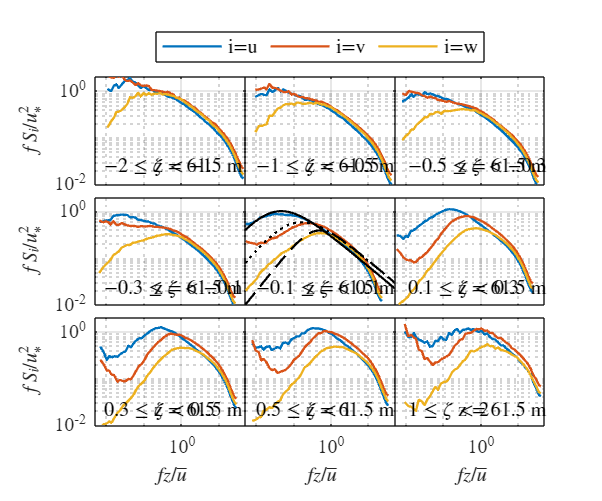


zetaThres = [-2 -1 -0.5 -0.3 -0.1 0.1 0.3 0.5 1 2];
minU= 5;
indSensor = 2;

% f = Wind.f;
clear ind
for ii=1:numel(zetaThres)-1
    ind{ii} = find(U(indSensor,:)>minU &...
        zL(indSensor,:)>=zetaThres(ii) &...
        zL(indSensor,:)<zetaThres(ii+1) & ...
        Result_RA(1,:) == 1 & ...
        meanDir(1,:)> 190 & ...
        meanDir(1,:)<350);
end


clf;close all
figure('position',[360.0000   68.3333  840  700])
tiledlayout(3,3,"TileSpacing","tight")
clear x y
for ii=1:numel(ind)
    nexttile
    x = f.*z(indSensor)./median(U(indSensor,ind{ii}),2,'omitnan');
    y = median(f.*squeeze(Su(indSensor,ind{ii},:))'./u_star(indSensor,ind{ii}).^2,2,'omitnan');
    loglog(x,y,'linewidth',1.2)
    hold on

    y = median(f.*squeeze(Sv(indSensor,ind{ii},:))'./u_star(indSensor,ind{ii}).^2,2,'omitnan');
    loglog(x,y,'linewidth',1.2)

    y = median(f.*squeeze(Sw(indSensor,ind{ii},:))'./u_star(indSensor,ind{ii}).^2,2,'omitnan');
    loglog(x,y,'linewidth',1.2)

    if ii==2,
        leg=legend('i=u','i=v','i=w','location','northoutside','orientation','horizontal');
        set(leg,'interpreter','latex')
    end

    if ii==5,
        x = logspace(log10(5e-3),log10(50),100);
        y = 102.*x./(1+33.*x).^(5/3);   
        plot(x,y,'k','linewidth',1.1)

        y = 17.*x./(1+9.5.*x).^(5/3);   
        plot(x,y,'k:','linewidth',1.1)

        y = 2.*x./(1+5.*(x).^(5/3));  
        plot(x,y,'k--','linewidth',1.1)
    
    end

    if ii<7,
        set(gca,'XTickLabel',[]);
    else
        xlabel('$fz/\overline{u}$','interpreter','latex')
    end

    if ii~=1 & ii~=4 & ii~=7,
        set(gca,'YTickLabel',[]);
    else
        ylabel('$f S_i /u^2_*$','interpreter','latex')
    end

    xlim([5e-3,50])
    ylim([1e-2,2])
    grid on

    txtStr = ['$',num2str(zetaThres(ii),2),' \leq \zeta <',num2str(zetaThres(ii+1),2),' $'];
    label([txtStr],0.03,0.03);
    label(['z = ',num2str(z(indSensor)),' m'],0.97,0.03,'alignement','right');
end

set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',10,'FontName','Times')